# Create Deep Learning Network Architecture with Pretrained Parameters ResNet-50

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 26-Dec-2022 14:16:51

## Load the Pretrained Parameters

params = load("D:\NITPY PhD\CET_Work\CET_Matlab\Folder_Processing\params_2022_12_26__14_16_37.mat");

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([224 224 1],"Name","imageinput")
    convolution2dLayer([7 7],64,"Name","conv","Padding","same","Stride",[2 2])
    batchNormalizationLayer("Name","bn_conv1","Epsilon",0.001,"Offset",params.bn_conv1.Offset,"Scale",params.bn_conv1.Scale,"TrainedMean",params.bn_conv1.TrainedMean,"TrainedVariance",params.bn_conv1.TrainedVariance)
    reluLayer("Name","activation_1_relu")
    maxPooling2dLayer([3 3],"Name","max_pooling2d_1","Padding",[1 1 1 1],"Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","res2a_branch2a","BiasLearnRateFactor",0,"Bias",params.res2a_branch2a.Bias,"Weights",params.res2a_branch2a.Weights)
    batchNormalizationLayer("Name","bn2a_branch2a","Epsilon",0.001,"Offset",params.bn2a_branch2a.Offset,"Scale",params.bn2a_branch2a.Scale,"TrainedMean",params.bn2a_branch2a.TrainedMean,"TrainedVariance",params.bn2a_branch2a.TrainedVariance)
    reluLayer("Name","activation_2_relu")
    convolution2dLayer([3 3],64,"Name","res2a_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res2a_branch2b.Bias,"Weights",params.res2a_branch2b.Weights)
    batchNormalizationLayer("Name","bn2a_branch2b","Epsilon",0.001,"Offset",params.bn2a_branch2b.Offset,"Scale",params.bn2a_branch2b.Scale,"TrainedMean",params.bn2a_branch2b.TrainedMean,"TrainedVariance",params.bn2a_branch2b.TrainedVariance)
    reluLayer("Name","activation_3_relu")
    convolution2dLayer([1 1],256,"Name","res2a_branch2c","BiasLearnRateFactor",0,"Bias",params.res2a_branch2c.Bias,"Weights",params.res2a_branch2c.Weights)
    batchNormalizationLayer("Name","bn2a_branch2c","Epsilon",0.001,"Offset",params.bn2a_branch2c.Offset,"Scale",params.bn2a_branch2c.Scale,"TrainedMean",params.bn2a_branch2c.TrainedMean,"TrainedVariance",params.bn2a_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res2a_branch1","BiasLearnRateFactor",0,"Bias",params.res2a_branch1.Bias,"Weights",params.res2a_branch1.Weights)
    batchNormalizationLayer("Name","bn2a_branch1","Epsilon",0.001,"Offset",params.bn2a_branch1.Offset,"Scale",params.bn2a_branch1.Scale,"TrainedMean",params.bn2a_branch1.TrainedMean,"TrainedVariance",params.bn2a_branch1.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_1")
    reluLayer("Name","activation_4_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","res2b_branch2a","BiasLearnRateFactor",0,"Bias",params.res2b_branch2a.Bias,"Weights",params.res2b_branch2a.Weights)
    batchNormalizationLayer("Name","bn2b_branch2a","Epsilon",0.001,"Offset",params.bn2b_branch2a.Offset,"Scale",params.bn2b_branch2a.Scale,"TrainedMean",params.bn2b_branch2a.TrainedMean,"TrainedVariance",params.bn2b_branch2a.TrainedVariance)
    reluLayer("Name","activation_5_relu")
    convolution2dLayer([3 3],64,"Name","res2b_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res2b_branch2b.Bias,"Weights",params.res2b_branch2b.Weights)
    batchNormalizationLayer("Name","bn2b_branch2b","Epsilon",0.001,"Offset",params.bn2b_branch2b.Offset,"Scale",params.bn2b_branch2b.Scale,"TrainedMean",params.bn2b_branch2b.TrainedMean,"TrainedVariance",params.bn2b_branch2b.TrainedVariance)
    reluLayer("Name","activation_6_relu")
    convolution2dLayer([1 1],256,"Name","res2b_branch2c","BiasLearnRateFactor",0,"Bias",params.res2b_branch2c.Bias,"Weights",params.res2b_branch2c.Weights)
    batchNormalizationLayer("Name","bn2b_branch2c","Epsilon",0.001,"Offset",params.bn2b_branch2c.Offset,"Scale",params.bn2b_branch2c.Scale,"TrainedMean",params.bn2b_branch2c.TrainedMean,"TrainedVariance",params.bn2b_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_2")
    reluLayer("Name","activation_7_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","res2c_branch2a","BiasLearnRateFactor",0,"Bias",params.res2c_branch2a.Bias,"Weights",params.res2c_branch2a.Weights)
    batchNormalizationLayer("Name","bn2c_branch2a","Epsilon",0.001,"Offset",params.bn2c_branch2a.Offset,"Scale",params.bn2c_branch2a.Scale,"TrainedMean",params.bn2c_branch2a.TrainedMean,"TrainedVariance",params.bn2c_branch2a.TrainedVariance)
    reluLayer("Name","activation_8_relu")
    convolution2dLayer([3 3],64,"Name","res2c_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res2c_branch2b.Bias,"Weights",params.res2c_branch2b.Weights)
    batchNormalizationLayer("Name","bn2c_branch2b","Epsilon",0.001,"Offset",params.bn2c_branch2b.Offset,"Scale",params.bn2c_branch2b.Scale,"TrainedMean",params.bn2c_branch2b.TrainedMean,"TrainedVariance",params.bn2c_branch2b.TrainedVariance)
    reluLayer("Name","activation_9_relu")
    convolution2dLayer([1 1],256,"Name","res2c_branch2c","BiasLearnRateFactor",0,"Bias",params.res2c_branch2c.Bias,"Weights",params.res2c_branch2c.Weights)
    batchNormalizationLayer("Name","bn2c_branch2c","Epsilon",0.001,"Offset",params.bn2c_branch2c.Offset,"Scale",params.bn2c_branch2c.Scale,"TrainedMean",params.bn2c_branch2c.TrainedMean,"TrainedVariance",params.bn2c_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_3")
    reluLayer("Name","activation_10_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],512,"Name","res3a_branch1","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",params.res3a_branch1.Bias,"Weights",params.res3a_branch1.Weights)
    batchNormalizationLayer("Name","bn3a_branch1","Epsilon",0.001,"Offset",params.bn3a_branch1.Offset,"Scale",params.bn3a_branch1.Scale,"TrainedMean",params.bn3a_branch1.TrainedMean,"TrainedVariance",params.bn3a_branch1.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","res3a_branch2a","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",params.res3a_branch2a.Bias,"Weights",params.res3a_branch2a.Weights)
    batchNormalizationLayer("Name","bn3a_branch2a","Epsilon",0.001,"Offset",params.bn3a_branch2a.Offset,"Scale",params.bn3a_branch2a.Scale,"TrainedMean",params.bn3a_branch2a.TrainedMean,"TrainedVariance",params.bn3a_branch2a.TrainedVariance)
    reluLayer("Name","activation_11_relu")
    convolution2dLayer([3 3],128,"Name","res3a_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res3a_branch2b.Bias,"Weights",params.res3a_branch2b.Weights)
    batchNormalizationLayer("Name","bn3a_branch2b","Epsilon",0.001,"Offset",params.bn3a_branch2b.Offset,"Scale",params.bn3a_branch2b.Scale,"TrainedMean",params.bn3a_branch2b.TrainedMean,"TrainedVariance",params.bn3a_branch2b.TrainedVariance)
    reluLayer("Name","activation_12_relu")
    convolution2dLayer([1 1],512,"Name","res3a_branch2c","BiasLearnRateFactor",0,"Bias",params.res3a_branch2c.Bias,"Weights",params.res3a_branch2c.Weights)
    batchNormalizationLayer("Name","bn3a_branch2c","Epsilon",0.001,"Offset",params.bn3a_branch2c.Offset,"Scale",params.bn3a_branch2c.Scale,"TrainedMean",params.bn3a_branch2c.TrainedMean,"TrainedVariance",params.bn3a_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_4")
    reluLayer("Name","activation_13_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","res3b_branch2a","BiasLearnRateFactor",0,"Bias",params.res3b_branch2a.Bias,"Weights",params.res3b_branch2a.Weights)
    batchNormalizationLayer("Name","bn3b_branch2a","Epsilon",0.001,"Offset",params.bn3b_branch2a.Offset,"Scale",params.bn3b_branch2a.Scale,"TrainedMean",params.bn3b_branch2a.TrainedMean,"TrainedVariance",params.bn3b_branch2a.TrainedVariance)
    reluLayer("Name","activation_14_relu")
    convolution2dLayer([3 3],128,"Name","res3b_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res3b_branch2b.Bias,"Weights",params.res3b_branch2b.Weights)
    batchNormalizationLayer("Name","bn3b_branch2b","Epsilon",0.001,"Offset",params.bn3b_branch2b.Offset,"Scale",params.bn3b_branch2b.Scale,"TrainedMean",params.bn3b_branch2b.TrainedMean,"TrainedVariance",params.bn3b_branch2b.TrainedVariance)
    reluLayer("Name","activation_15_relu")
    convolution2dLayer([1 1],512,"Name","res3b_branch2c","BiasLearnRateFactor",0,"Bias",params.res3b_branch2c.Bias,"Weights",params.res3b_branch2c.Weights)
    batchNormalizationLayer("Name","bn3b_branch2c","Epsilon",0.001,"Offset",params.bn3b_branch2c.Offset,"Scale",params.bn3b_branch2c.Scale,"TrainedMean",params.bn3b_branch2c.TrainedMean,"TrainedVariance",params.bn3b_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_5")
    reluLayer("Name","activation_16_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","res3c_branch2a","BiasLearnRateFactor",0,"Bias",params.res3c_branch2a.Bias,"Weights",params.res3c_branch2a.Weights)
    batchNormalizationLayer("Name","bn3c_branch2a","Epsilon",0.001,"Offset",params.bn3c_branch2a.Offset,"Scale",params.bn3c_branch2a.Scale,"TrainedMean",params.bn3c_branch2a.TrainedMean,"TrainedVariance",params.bn3c_branch2a.TrainedVariance)
    reluLayer("Name","activation_17_relu")
    convolution2dLayer([3 3],128,"Name","res3c_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res3c_branch2b.Bias,"Weights",params.res3c_branch2b.Weights)
    batchNormalizationLayer("Name","bn3c_branch2b","Epsilon",0.001,"Offset",params.bn3c_branch2b.Offset,"Scale",params.bn3c_branch2b.Scale,"TrainedMean",params.bn3c_branch2b.TrainedMean,"TrainedVariance",params.bn3c_branch2b.TrainedVariance)
    reluLayer("Name","activation_18_relu")
    convolution2dLayer([1 1],512,"Name","res3c_branch2c","BiasLearnRateFactor",0,"Bias",params.res3c_branch2c.Bias,"Weights",params.res3c_branch2c.Weights)
    batchNormalizationLayer("Name","bn3c_branch2c","Epsilon",0.001,"Offset",params.bn3c_branch2c.Offset,"Scale",params.bn3c_branch2c.Scale,"TrainedMean",params.bn3c_branch2c.TrainedMean,"TrainedVariance",params.bn3c_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_6")
    reluLayer("Name","activation_19_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","res3d_branch2a","BiasLearnRateFactor",0,"Bias",params.res3d_branch2a.Bias,"Weights",params.res3d_branch2a.Weights)
    batchNormalizationLayer("Name","bn3d_branch2a","Epsilon",0.001,"Offset",params.bn3d_branch2a.Offset,"Scale",params.bn3d_branch2a.Scale,"TrainedMean",params.bn3d_branch2a.TrainedMean,"TrainedVariance",params.bn3d_branch2a.TrainedVariance)
    reluLayer("Name","activation_20_relu")
    convolution2dLayer([3 3],128,"Name","res3d_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res3d_branch2b.Bias,"Weights",params.res3d_branch2b.Weights)
    batchNormalizationLayer("Name","bn3d_branch2b","Epsilon",0.001,"Offset",params.bn3d_branch2b.Offset,"Scale",params.bn3d_branch2b.Scale,"TrainedMean",params.bn3d_branch2b.TrainedMean,"TrainedVariance",params.bn3d_branch2b.TrainedVariance)
    reluLayer("Name","activation_21_relu")
    convolution2dLayer([1 1],512,"Name","res3d_branch2c","BiasLearnRateFactor",0,"Bias",params.res3d_branch2c.Bias,"Weights",params.res3d_branch2c.Weights)
    batchNormalizationLayer("Name","bn3d_branch2c","Epsilon",0.001,"Offset",params.bn3d_branch2c.Offset,"Scale",params.bn3d_branch2c.Scale,"TrainedMean",params.bn3d_branch2c.TrainedMean,"TrainedVariance",params.bn3d_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_7")
    reluLayer("Name","activation_22_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4a_branch2a","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",params.res4a_branch2a.Bias,"Weights",params.res4a_branch2a.Weights)
    batchNormalizationLayer("Name","bn4a_branch2a","Epsilon",0.001,"Offset",params.bn4a_branch2a.Offset,"Scale",params.bn4a_branch2a.Scale,"TrainedMean",params.bn4a_branch2a.TrainedMean,"TrainedVariance",params.bn4a_branch2a.TrainedVariance)
    reluLayer("Name","activation_23_relu")
    convolution2dLayer([3 3],256,"Name","res4a_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res4a_branch2b.Bias,"Weights",params.res4a_branch2b.Weights)
    batchNormalizationLayer("Name","bn4a_branch2b","Epsilon",0.001,"Offset",params.bn4a_branch2b.Offset,"Scale",params.bn4a_branch2b.Scale,"TrainedMean",params.bn4a_branch2b.TrainedMean,"TrainedVariance",params.bn4a_branch2b.TrainedVariance)
    reluLayer("Name","activation_24_relu")
    convolution2dLayer([1 1],1024,"Name","res4a_branch2c","BiasLearnRateFactor",0,"Bias",params.res4a_branch2c.Bias,"Weights",params.res4a_branch2c.Weights)
    batchNormalizationLayer("Name","bn4a_branch2c","Epsilon",0.001,"Offset",params.bn4a_branch2c.Offset,"Scale",params.bn4a_branch2c.Scale,"TrainedMean",params.bn4a_branch2c.TrainedMean,"TrainedVariance",params.bn4a_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],1024,"Name","res4a_branch1","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",params.res4a_branch1.Bias,"Weights",params.res4a_branch1.Weights)
    batchNormalizationLayer("Name","bn4a_branch1","Epsilon",0.001,"Offset",params.bn4a_branch1.Offset,"Scale",params.bn4a_branch1.Scale,"TrainedMean",params.bn4a_branch1.TrainedMean,"TrainedVariance",params.bn4a_branch1.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_8")
    reluLayer("Name","activation_25_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4b_branch2a","BiasLearnRateFactor",0,"Bias",params.res4b_branch2a.Bias,"Weights",params.res4b_branch2a.Weights)
    batchNormalizationLayer("Name","bn4b_branch2a","Epsilon",0.001,"Offset",params.bn4b_branch2a.Offset,"Scale",params.bn4b_branch2a.Scale,"TrainedMean",params.bn4b_branch2a.TrainedMean,"TrainedVariance",params.bn4b_branch2a.TrainedVariance)
    reluLayer("Name","activation_26_relu")
    convolution2dLayer([3 3],256,"Name","res4b_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res4b_branch2b.Bias,"Weights",params.res4b_branch2b.Weights)
    batchNormalizationLayer("Name","bn4b_branch2b","Epsilon",0.001,"Offset",params.bn4b_branch2b.Offset,"Scale",params.bn4b_branch2b.Scale,"TrainedMean",params.bn4b_branch2b.TrainedMean,"TrainedVariance",params.bn4b_branch2b.TrainedVariance)
    reluLayer("Name","activation_27_relu")
    convolution2dLayer([1 1],1024,"Name","res4b_branch2c","BiasLearnRateFactor",0,"Bias",params.res4b_branch2c.Bias,"Weights",params.res4b_branch2c.Weights)
    batchNormalizationLayer("Name","bn4b_branch2c","Epsilon",0.001,"Offset",params.bn4b_branch2c.Offset,"Scale",params.bn4b_branch2c.Scale,"TrainedMean",params.bn4b_branch2c.TrainedMean,"TrainedVariance",params.bn4b_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_9")
    reluLayer("Name","activation_28_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4c_branch2a","BiasLearnRateFactor",0,"Bias",params.res4c_branch2a.Bias,"Weights",params.res4c_branch2a.Weights)
    batchNormalizationLayer("Name","bn4c_branch2a","Epsilon",0.001,"Offset",params.bn4c_branch2a.Offset,"Scale",params.bn4c_branch2a.Scale,"TrainedMean",params.bn4c_branch2a.TrainedMean,"TrainedVariance",params.bn4c_branch2a.TrainedVariance)
    reluLayer("Name","activation_29_relu")
    convolution2dLayer([3 3],256,"Name","res4c_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res4c_branch2b.Bias,"Weights",params.res4c_branch2b.Weights)
    batchNormalizationLayer("Name","bn4c_branch2b","Epsilon",0.001,"Offset",params.bn4c_branch2b.Offset,"Scale",params.bn4c_branch2b.Scale,"TrainedMean",params.bn4c_branch2b.TrainedMean,"TrainedVariance",params.bn4c_branch2b.TrainedVariance)
    reluLayer("Name","activation_30_relu")
    convolution2dLayer([1 1],1024,"Name","res4c_branch2c","BiasLearnRateFactor",0,"Bias",params.res4c_branch2c.Bias,"Weights",params.res4c_branch2c.Weights)
    batchNormalizationLayer("Name","bn4c_branch2c","Epsilon",0.001,"Offset",params.bn4c_branch2c.Offset,"Scale",params.bn4c_branch2c.Scale,"TrainedMean",params.bn4c_branch2c.TrainedMean,"TrainedVariance",params.bn4c_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_10")
    reluLayer("Name","activation_31_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4d_branch2a","BiasLearnRateFactor",0,"Bias",params.res4d_branch2a.Bias,"Weights",params.res4d_branch2a.Weights)
    batchNormalizationLayer("Name","bn4d_branch2a","Epsilon",0.001,"Offset",params.bn4d_branch2a.Offset,"Scale",params.bn4d_branch2a.Scale,"TrainedMean",params.bn4d_branch2a.TrainedMean,"TrainedVariance",params.bn4d_branch2a.TrainedVariance)
    reluLayer("Name","activation_32_relu")
    convolution2dLayer([3 3],256,"Name","res4d_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res4d_branch2b.Bias,"Weights",params.res4d_branch2b.Weights)
    batchNormalizationLayer("Name","bn4d_branch2b","Epsilon",0.001,"Offset",params.bn4d_branch2b.Offset,"Scale",params.bn4d_branch2b.Scale,"TrainedMean",params.bn4d_branch2b.TrainedMean,"TrainedVariance",params.bn4d_branch2b.TrainedVariance)
    reluLayer("Name","activation_33_relu")
    convolution2dLayer([1 1],1024,"Name","res4d_branch2c","BiasLearnRateFactor",0,"Bias",params.res4d_branch2c.Bias,"Weights",params.res4d_branch2c.Weights)
    batchNormalizationLayer("Name","bn4d_branch2c","Epsilon",0.001,"Offset",params.bn4d_branch2c.Offset,"Scale",params.bn4d_branch2c.Scale,"TrainedMean",params.bn4d_branch2c.TrainedMean,"TrainedVariance",params.bn4d_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_11")
    reluLayer("Name","activation_34_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4e_branch2a","BiasLearnRateFactor",0,"Bias",params.res4e_branch2a.Bias,"Weights",params.res4e_branch2a.Weights)
    batchNormalizationLayer("Name","bn4e_branch2a","Epsilon",0.001,"Offset",params.bn4e_branch2a.Offset,"Scale",params.bn4e_branch2a.Scale,"TrainedMean",params.bn4e_branch2a.TrainedMean,"TrainedVariance",params.bn4e_branch2a.TrainedVariance)
    reluLayer("Name","activation_35_relu")
    convolution2dLayer([3 3],256,"Name","res4e_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res4e_branch2b.Bias,"Weights",params.res4e_branch2b.Weights)
    batchNormalizationLayer("Name","bn4e_branch2b","Epsilon",0.001,"Offset",params.bn4e_branch2b.Offset,"Scale",params.bn4e_branch2b.Scale,"TrainedMean",params.bn4e_branch2b.TrainedMean,"TrainedVariance",params.bn4e_branch2b.TrainedVariance)
    reluLayer("Name","activation_36_relu")
    convolution2dLayer([1 1],1024,"Name","res4e_branch2c","BiasLearnRateFactor",0,"Bias",params.res4e_branch2c.Bias,"Weights",params.res4e_branch2c.Weights)
    batchNormalizationLayer("Name","bn4e_branch2c","Epsilon",0.001,"Offset",params.bn4e_branch2c.Offset,"Scale",params.bn4e_branch2c.Scale,"TrainedMean",params.bn4e_branch2c.TrainedMean,"TrainedVariance",params.bn4e_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_12")
    reluLayer("Name","activation_37_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","res4f_branch2a","BiasLearnRateFactor",0,"Bias",params.res4f_branch2a.Bias,"Weights",params.res4f_branch2a.Weights)
    batchNormalizationLayer("Name","bn4f_branch2a","Epsilon",0.001,"Offset",params.bn4f_branch2a.Offset,"Scale",params.bn4f_branch2a.Scale,"TrainedMean",params.bn4f_branch2a.TrainedMean,"TrainedVariance",params.bn4f_branch2a.TrainedVariance)
    reluLayer("Name","activation_38_relu")
    convolution2dLayer([3 3],256,"Name","res4f_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res4f_branch2b.Bias,"Weights",params.res4f_branch2b.Weights)
    batchNormalizationLayer("Name","bn4f_branch2b","Epsilon",0.001,"Offset",params.bn4f_branch2b.Offset,"Scale",params.bn4f_branch2b.Scale,"TrainedMean",params.bn4f_branch2b.TrainedMean,"TrainedVariance",params.bn4f_branch2b.TrainedVariance)
    reluLayer("Name","activation_39_relu")
    convolution2dLayer([1 1],1024,"Name","res4f_branch2c","BiasLearnRateFactor",0,"Bias",params.res4f_branch2c.Bias,"Weights",params.res4f_branch2c.Weights)
    batchNormalizationLayer("Name","bn4f_branch2c","Epsilon",0.001,"Offset",params.bn4f_branch2c.Offset,"Scale",params.bn4f_branch2c.Scale,"TrainedMean",params.bn4f_branch2c.TrainedMean,"TrainedVariance",params.bn4f_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_13")
    reluLayer("Name","activation_40_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],512,"Name","res5a_branch2a","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",params.res5a_branch2a.Bias,"Weights",params.res5a_branch2a.Weights)
    batchNormalizationLayer("Name","bn5a_branch2a","Epsilon",0.001,"Offset",params.bn5a_branch2a.Offset,"Scale",params.bn5a_branch2a.Scale,"TrainedMean",params.bn5a_branch2a.TrainedMean,"TrainedVariance",params.bn5a_branch2a.TrainedVariance)
    reluLayer("Name","activation_41_relu")
    convolution2dLayer([3 3],512,"Name","res5a_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res5a_branch2b.Bias,"Weights",params.res5a_branch2b.Weights)
    batchNormalizationLayer("Name","bn5a_branch2b","Epsilon",0.001,"Offset",params.bn5a_branch2b.Offset,"Scale",params.bn5a_branch2b.Scale,"TrainedMean",params.bn5a_branch2b.TrainedMean,"TrainedVariance",params.bn5a_branch2b.TrainedVariance)
    reluLayer("Name","activation_42_relu")
    convolution2dLayer([1 1],2048,"Name","res5a_branch2c","BiasLearnRateFactor",0,"Bias",params.res5a_branch2c.Bias,"Weights",params.res5a_branch2c.Weights)
    batchNormalizationLayer("Name","bn5a_branch2c","Epsilon",0.001,"Offset",params.bn5a_branch2c.Offset,"Scale",params.bn5a_branch2c.Scale,"TrainedMean",params.bn5a_branch2c.TrainedMean,"TrainedVariance",params.bn5a_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],2048,"Name","res5a_branch1","BiasLearnRateFactor",0,"Stride",[2 2],"Bias",params.res5a_branch1.Bias,"Weights",params.res5a_branch1.Weights)
    batchNormalizationLayer("Name","bn5a_branch1","Epsilon",0.001,"Offset",params.bn5a_branch1.Offset,"Scale",params.bn5a_branch1.Scale,"TrainedMean",params.bn5a_branch1.TrainedMean,"TrainedVariance",params.bn5a_branch1.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_14")
    reluLayer("Name","activation_43_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],512,"Name","res5b_branch2a","BiasLearnRateFactor",0,"Bias",params.res5b_branch2a.Bias,"Weights",params.res5b_branch2a.Weights)
    batchNormalizationLayer("Name","bn5b_branch2a","Epsilon",0.001,"Offset",params.bn5b_branch2a.Offset,"Scale",params.bn5b_branch2a.Scale,"TrainedMean",params.bn5b_branch2a.TrainedMean,"TrainedVariance",params.bn5b_branch2a.TrainedVariance)
    reluLayer("Name","activation_44_relu")
    convolution2dLayer([3 3],512,"Name","res5b_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res5b_branch2b.Bias,"Weights",params.res5b_branch2b.Weights)
    batchNormalizationLayer("Name","bn5b_branch2b","Epsilon",0.001,"Offset",params.bn5b_branch2b.Offset,"Scale",params.bn5b_branch2b.Scale,"TrainedMean",params.bn5b_branch2b.TrainedMean,"TrainedVariance",params.bn5b_branch2b.TrainedVariance)
    reluLayer("Name","activation_45_relu")
    convolution2dLayer([1 1],2048,"Name","res5b_branch2c","BiasLearnRateFactor",0,"Bias",params.res5b_branch2c.Bias,"Weights",params.res5b_branch2c.Weights)
    batchNormalizationLayer("Name","bn5b_branch2c","Epsilon",0.001,"Offset",params.bn5b_branch2c.Offset,"Scale",params.bn5b_branch2c.Scale,"TrainedMean",params.bn5b_branch2c.TrainedMean,"TrainedVariance",params.bn5b_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_15")
    reluLayer("Name","activation_46_relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],512,"Name","res5c_branch2a","BiasLearnRateFactor",0,"Bias",params.res5c_branch2a.Bias,"Weights",params.res5c_branch2a.Weights)
    batchNormalizationLayer("Name","bn5c_branch2a","Epsilon",0.001,"Offset",params.bn5c_branch2a.Offset,"Scale",params.bn5c_branch2a.Scale,"TrainedMean",params.bn5c_branch2a.TrainedMean,"TrainedVariance",params.bn5c_branch2a.TrainedVariance)
    reluLayer("Name","activation_47_relu")
    convolution2dLayer([3 3],512,"Name","res5c_branch2b","BiasLearnRateFactor",0,"Padding","same","Bias",params.res5c_branch2b.Bias,"Weights",params.res5c_branch2b.Weights)
    batchNormalizationLayer("Name","bn5c_branch2b","Epsilon",0.001,"Offset",params.bn5c_branch2b.Offset,"Scale",params.bn5c_branch2b.Scale,"TrainedMean",params.bn5c_branch2b.TrainedMean,"TrainedVariance",params.bn5c_branch2b.TrainedVariance)
    reluLayer("Name","activation_48_relu")
    convolution2dLayer([1 1],2048,"Name","res5c_branch2c","BiasLearnRateFactor",0,"Bias",params.res5c_branch2c.Bias,"Weights",params.res5c_branch2c.Weights)
    batchNormalizationLayer("Name","bn5c_branch2c","Epsilon",0.001,"Offset",params.bn5c_branch2c.Offset,"Scale",params.bn5c_branch2c.Scale,"TrainedMean",params.bn5c_branch2c.TrainedMean,"TrainedVariance",params.bn5c_branch2c.TrainedVariance)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_16")
    reluLayer("Name","activation_49_relu")
    globalAveragePooling2dLayer("Name","avg_pool")
    fullyConnectedLayer(1,"Name","fc")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"max_pooling2d_1","res2a_branch2a");
lgraph = connectLayers(lgraph,"max_pooling2d_1","res2a_branch1");
lgraph = connectLayers(lgraph,"bn2a_branch1","add_1/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c","add_1/in1");
lgraph = connectLayers(lgraph,"activation_4_relu","res2b_branch2a");
lgraph = connectLayers(lgraph,"activation_4_relu","add_2/in2");
lgraph = connectLayers(lgraph,"bn2b_branch2c","add_2/in1");
lgraph = connectLayers(lgraph,"activation_7_relu","res2c_branch2a");
lgraph = connectLayers(lgraph,"activation_7_relu","add_3/in2");
lgraph = connectLayers(lgraph,"bn2c_branch2c","add_3/in1");
lgraph = connectLayers(lgraph,"activation_10_relu","res3a_branch1");
lgraph = connectLayers(lgraph,"activation_10_relu","res3a_branch2a");
lgraph = connectLayers(lgraph,"bn3a_branch1","add_4/in2");
lgraph = connectLayers(lgraph,"bn3a_branch2c","add_4/in1");
lgraph = connectLayers(lgraph,"activation_13_relu","res3b_branch2a");
lgraph = connectLayers(lgraph,"activation_13_relu","add_5/in2");
lgraph = connectLayers(lgraph,"bn3b_branch2c","add_5/in1");
lgraph = connectLayers(lgraph,"activation_16_relu","res3c_branch2a");
lgraph = connectLayers(lgraph,"activation_16_relu","add_6/in2");
lgraph = connectLayers(lgraph,"bn3c_branch2c","add_6/in1");
lgraph = connectLayers(lgraph,"activation_19_relu","res3d_branch2a");
lgraph = connectLayers(lgraph,"activation_19_relu","add_7/in2");
lgraph = connectLayers(lgraph,"bn3d_branch2c","add_7/in1");
lgraph = connectLayers(lgraph,"activation_22_relu","res4a_branch2a");
lgraph = connectLayers(lgraph,"activation_22_relu","res4a_branch1");
lgraph = connectLayers(lgraph,"bn4a_branch2c","add_8/in1");
lgraph = connectLayers(lgraph,"bn4a_branch1","add_8/in2");
lgraph = connectLayers(lgraph,"activation_25_relu","res4b_branch2a");
lgraph = connectLayers(lgraph,"activation_25_relu","add_9/in2");
lgraph = connectLayers(lgraph,"bn4b_branch2c","add_9/in1");
lgraph = connectLayers(lgraph,"activation_28_relu","res4c_branch2a");
lgraph = connectLayers(lgraph,"activation_28_relu","add_10/in2");
lgraph = connectLayers(lgraph,"bn4c_branch2c","add_10/in1");
lgraph = connectLayers(lgraph,"activation_31_relu","res4d_branch2a");
lgraph = connectLayers(lgraph,"activation_31_relu","add_11/in2");
lgraph = connectLayers(lgraph,"bn4d_branch2c","add_11/in1");
lgraph = connectLayers(lgraph,"activation_34_relu","res4e_branch2a");
lgraph = connectLayers(lgraph,"activation_34_relu","add_12/in2");
lgraph = connectLayers(lgraph,"bn4e_branch2c","add_12/in1");
lgraph = connectLayers(lgraph,"activation_37_relu","res4f_branch2a");
lgraph = connectLayers(lgraph,"activation_37_relu","add_13/in2");
lgraph = connectLayers(lgraph,"bn4f_branch2c","add_13/in1");
lgraph = connectLayers(lgraph,"activation_40_relu","res5a_branch2a");
lgraph = connectLayers(lgraph,"activation_40_relu","res5a_branch1");
lgraph = connectLayers(lgraph,"bn5a_branch1","add_14/in2");
lgraph = connectLayers(lgraph,"bn5a_branch2c","add_14/in1");
lgraph = connectLayers(lgraph,"activation_43_relu","res5b_branch2a");
lgraph = connectLayers(lgraph,"activation_43_relu","add_15/in2");
lgraph = connectLayers(lgraph,"bn5b_branch2c","add_15/in1");
lgraph = connectLayers(lgraph,"activation_46_relu","res5c_branch2a");
lgraph = connectLayers(lgraph,"activation_46_relu","add_16/in2");
lgraph = connectLayers(lgraph,"bn5c_branch2c","add_16/in1");

## Plot Layers

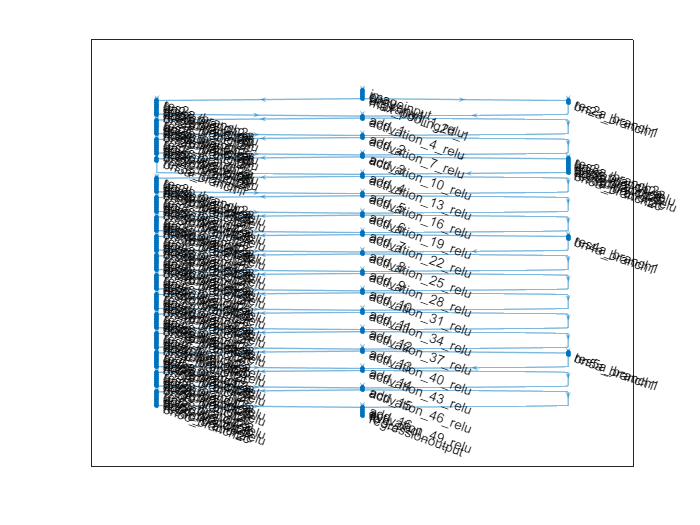

plot(lgraph);

fullData = readtable("SCParameter_From_V_PSNR+MedNode.csv");
imageData = fullData.Name;
nImg = height(imageData)

nImg = 3648


imds = imageDatastore(imageData);

data = fullData.SC_PSNR;

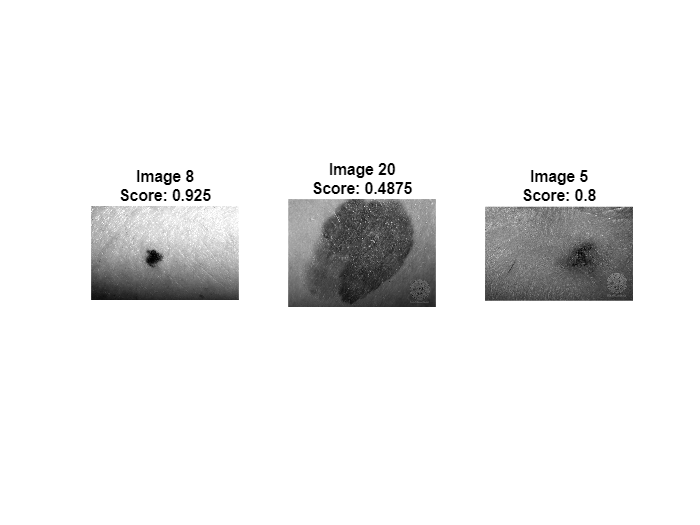

figure
t = tiledlayout(1,3);
idx1 = 8;
displayImageAndScores(t,readimage(imds,idx1), ...
    data(idx1),"Image "+ idx1)
idx2 = 20;
displayImageAndScores(t,readimage(imds,idx2), ...
    data(idx2),"Image "+idx2)
idx3 = 5;
displayImageAndScores(t,readimage(imds,idx3), ...
    data(idx3),"Image "+idx3)

numTrain = floor(0.80 * nImg)

numTrain = 2918

numVal = floor(0.05 * nImg)

numVal = 182


Idx = randperm(nImg);

idxTrain = Idx(1:numTrain);
idxVal = Idx(numTrain+1:numTrain+numVal);
idxTest = Idx(numTrain+numVal+1:nImg);

trainData = fullData(idxTrain,:);
valData = fullData(idxVal,:);
testData = fullData(idxTest,:);

trainDSI = fullData(idxTrain,:).SC_PSNR;
valDSI = fullData(idxVal,:).SC_PSNR;
testDSI = fullData(idxTest,:).SC_PSNR;

imageAugmenter = imageDataAugmenter( ...
    'RandXTranslation',[-3 3], ...
    'RandYTranslation',[-3 3],...
    'RandXReflection', true, ...
    'RandYReflection',true)

imageAugmenter =   imageDataAugmenter with properties:

           FillValue: 0
     RandXReflection: 1
     RandYReflection: 1
        RandRotation: [0 0]
           RandScale: [1 1]
          RandXScale: [1 1]
          RandYScale: [1 1]
          RandXShear: [0 0]
          RandYShear: [0 0]
    RandXTranslation: [-3 3]
    RandYTranslation: [-3 3]


trainds = augmentedImageDatastore([224 224],trainData,'DataAugmentation',imageAugmenter);
valds = augmentedImageDatastore([224 224],valData,'DataAugmentation',imageAugmenter);
testds = augmentedImageDatastore([224 224],testData,'DataAugmentation',imageAugmenter);

% Define the parameters for the network 
options=trainingOptions('sgdm',...
    'InitialLearnRate', 0.03, ...
    'Momentum',0.9,...
    'L2Regularization',0.0005,...
    'MaxEpochs',30,...
    'MiniBatchSize',16,...
    'VerboseFrequency',20,...
    'LearnRateSchedule','piecewise',... 
    'ExecutionEnvironment','gpu',...
    'Shuffle','every-epoch',...
    "OutputNetwork", 'best-validation-loss',...
    'ValidationData',{valds,valDSI}, ...
    'ValidationFrequency',40, ...
    'ValidationPatience',50,...
    'GradientThresholdMethod','l2norm',...
    'GradientThreshold',0.05);
%'Plots','training-progress',...

ccnet = trainNetwork(trainds,lgraph,options)

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |         1.34 |         1.59 |       0.8950 |       1.2587 |          0.0300 |
|       1 |          20 |       00:00:24 |         0.51 |              |       0.1325 |              |          0.0300 |
|       1 |          40 |       00:00:47 |         0.52 |         0.57 |       0.1363 |       0.1637 |          0.0300 |
|       1 |          60 |       00:01:06 |         0.61 |              |       0.1865 |              |          0.

ccnet =   DAGNetwork with properties:

         Layers: [176×1 nnet.cnn.layer.Layer]
    Connections: [191×2 table]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


Train_Predicted = abs(predict(ccnet,trainds));
Test_Predicted = abs(predict(ccnet,testds));

Train_Pred_mae = errperf(trainDSI,Train_Predicted,'mae')

Train_Pred_mae = single
0.0800

Test_Pred_mae = errperf(testDSI,Test_Predicted,'mae')

Test_Pred_mae = single
0.1024

Train_Pred_rmse = errperf(trainDSI,Train_Predicted,'rmse')

Train_Pred_rmse = single
0.1342

Test_Pred_rmse = errperf(testDSI,Test_Predicted,'rmse')

Test_Pred_rmse = single
0.1665

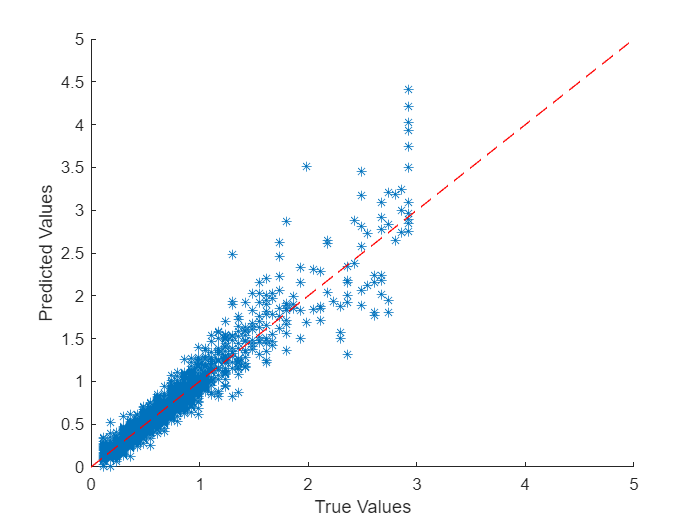

figure
scatter(trainDSI,Train_Predicted,'*')
xlabel("True Values")
ylabel("Predicted Values")

hold on
plot([0 5], [0 5],'r--')

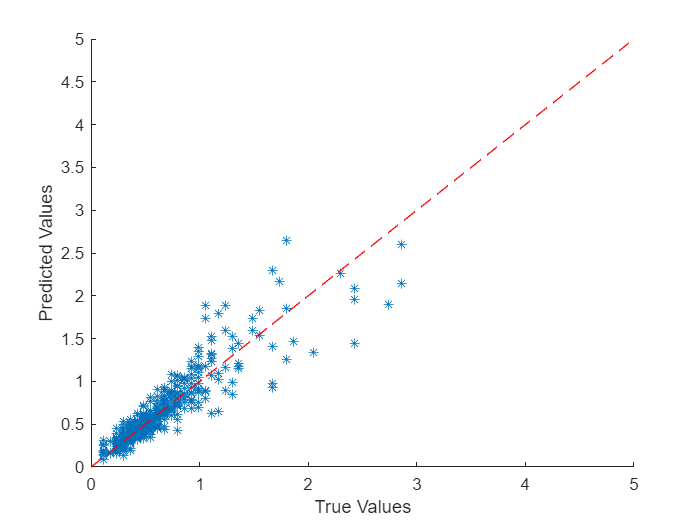

figure
scatter(testDSI,Test_Predicted,'*')
xlabel("True Values")
ylabel("Predicted Values")

hold on
plot([0 5], [0 5],'r--')

# **GradCAM Analysis**

% mytestds = imresize(imread("08_Orig.jpg"),[224 224]);

% My_Test_Predicted = abs(predict(ccnet,mytestds))

% %mytestDSI = testData(30,:).DSI
% mytestDSI = 0.12508

% featureLayer = 'activation_49_relu';
% reductionLayer = 'fc';

% reductionFcn = @(x)x;

% scoreMap = gradCAM(ccnet,mytestds,reductionFcn, ...
%     'ReductionLayer',reductionLayer, ...
%     'FeatureLayer',featureLayer);

% ax(1) = subplot(1,2,1);
% imshow(mytestds)
% title("True IQ = " + mytestDSI + '\newline Pred IQ = ' + My_Test_Predicted)
% colormap(ax(1),'gray')
% 
% ax(2) = subplot(1,2,2);
% imshow(mytestds)
% hold on
% imagesc(scoreMap,'AlphaData',1)
% colormap(ax(2),'jet')
% title("GradCAM")
% hold off

OrigtestData = readtable("Simulated_Test1.csv");
imagetestData = OrigtestData.Name;
ntestImg = height(imagetestData)

ntestImg = 152


Origtestimds = imageDatastore(imagetestData);

OrigtestSC = OrigtestData.SC ;

Origtestds = augmentedImageDatastore([224 224],OrigtestData);
Origtest_SC_Predicted = abs(predict(ccnet,Origtestds));

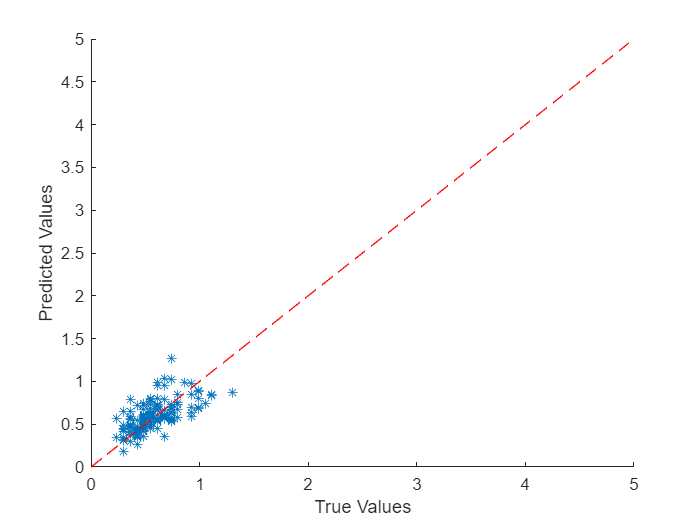

figure
scatter(OrigtestSC,Origtest_SC_Predicted,'*')
xlabel("True Values")
ylabel("Predicted Values")

hold on
plot([0 5], [0 5],'r--')

Origtest_Pred_mae = errperf(OrigtestSC,Origtest_SC_Predicted,'mae')

Origtest_Pred_mae = single
0.1231

Origtest_Pred_rmse = errperf(OrigtestSC,Origtest_SC_Predicted,'rmse')

Origtest_Pred_rmse = single
0.1603

T= table(imagetestData,Origtest_SC_Predicted);
writetable(T,'ResNet_15epoch_Test1_25.02.23.xls');